# Car model and behaviour

This livescript is a brief manual in support of the app ***carmodel_and_behaviour.mlapp***.   This is a simple interface to understand the modelling and behaviour of simple car models, subject to disturbances such as wind and road slopes.    

See website for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/mainindex](https://sites.google.com/sheffield.ac.uk/controleducation/mainindex)

A group of similar files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

A logical next file is ***cruisecontrol.mlapp*** which looks at how to control the speed using a PI compensator.

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Engineeering context

- Open-loop behaviour

- Time constant and gain analysis

- Impact of disturbances on steady-state

- Interface and user interaction

## 1. Engineering context

We consider a car can be represented as a simple mass-damper model, the damping representing friction which is assumed proportional to velocity. So with mass *M*, damping *B *which represents frictional forces,  throttle position *f *(assume values between 0 and 1), and C relates to the maximum engine power available, the model is:


$$M\frac{\textrm{dv}}{\textrm{dt}}+\textrm{Bv}=\textrm{Cf}$$


In practice the road may not be level and have a slope $\theta$. Also there may be wind of speed *w*. These two factors affect the model in the following way.

 $M\frac{\textrm{dv}}{\textrm{dt}}+B\left(v+w\right)+\textrm{Mgsin}\left(\theta \right)=\textrm{Cf}$    [Hereafter assume small angles so $\theta =\sin \left(\theta \right)$.]

Hence, this can be represented as a transfer function model with one output (velocity) and three inputs (throttle, slope, wind).


$$v\left(s\right)=\frac{C}{\textrm{Ms}+B}f\left(s\right)-\frac{\textrm{Mg}}{\textrm{Ms}+B}\theta \left(s\right)-\frac{B}{\textrm{Ms}+B}w\left(s\right)$$


% y = G*u + F*slope + W*wind
M=600; B=200; C=5000;
G=tf(C,[M,B]); % car model
W=tf(B,[M,B]);     % wind to velocity
F=tf(M*10,[M,B]);  % slope to velocity

## 2. Open-loop behaviour 

One can determine the overall response using superposition as indicated in the equation above.

disp('Section 2 illustrations below')

Section 2 illustrations below


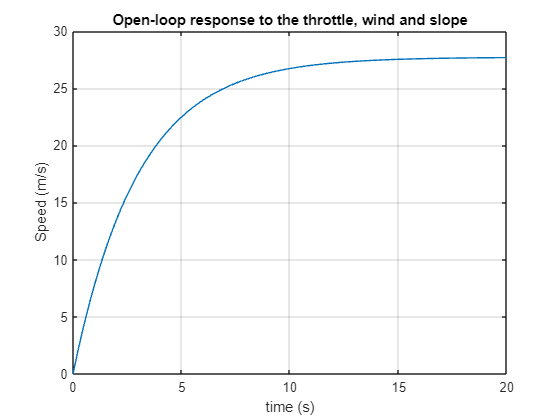


% y = G*u + F*slope + W*wind
% Define the step responses
runtime =20;
time=linspace(0,runtime,101);
yr = step(G,time);  % scale by throttle percentage
yw = step(W,time);  % scale by wind speed
ys = step(F,time);  % scale by sin(slope)

%
wind =10;
slope =10;
throttle =0.5;
y = yr*throttle+yw*wind+ys*sin(slope*pi/180);
plot(time,y); grid
title('Open-loop response to the throttle, wind and slope')
xlabel('time (s)')
ylabel('Speed (m/s)')

## 3. Time constant and gain analysis

As the basic model is a 1st order differential equation, it is common place to model these in time constant form.


$$M\frac{\textrm{dv}}{\textrm{dt}}+\textrm{Bv}=\textrm{Cf}\;\;\Leftrightarrow \;\;\;\frac{M}{B}\frac{\textrm{dv}}{\textrm{dt}}+v=\frac{C}{B}f\;\;\;\Leftrightarrow \;\;\;\;T\frac{\textrm{dv}}{\textrm{dt}}+v=\textrm{Kf}$$


The time constant *T *gives an indicator of the convergence rate (typically about 3 time constants to be within 5% of steady-state) and the system gain *K* indicates  the expected steady-state (with no disturbances) and *f=1*. The bottom left figure in the app (see illustration in section 5 below) shows the computation of these two parameters. The time constant is also included in the legend of the bottom right figure for record keeping.

disp('Section 3 illustrations below')

Section 3 illustrations below


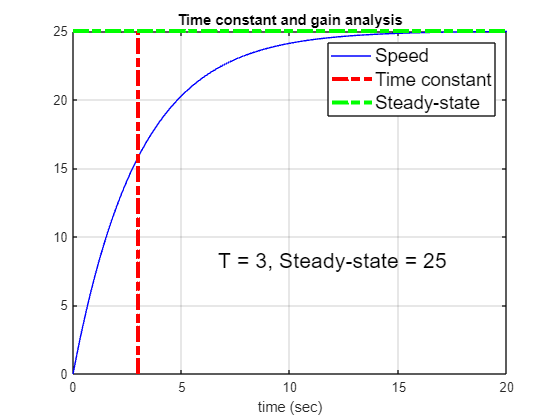

T=M/B;
Gss=C/B;
plot(time,yr,'b');
hold('on') ;
plot([T,T],[0,Gss],'r-.','linewidth',3)
plot([0,runtime],[Gss,Gss],'g-.','linewidth',3);
kkk=legend('Speed','Time constant','Steady-state');
set(kkk,'fontsize',14);
text(runtime/3,Gss/3,['T = ',num2str(T),', Steady-state = ',num2str(Gss)],'fontsize', 16);
title('Time constant and gain analysis')
xlabel('time (sec)');
grid('on');
hold('off');

## 4. Impact of disturbances on steady-state

Taking the full model, users will notice that the time constant is independent of the slope and wind, but the expected steady-state is not.


$$M\frac{\textrm{dv}}{\textrm{dt}}+B\left(v+w\right)+\textrm{Mg}\;\sin \left(\theta \right)=\textrm{Cf}\;\;\;\;\;\;\;\;\;\Leftrightarrow \;\;\;\;\;\;\;\;T\frac{\textrm{dv}}{\textrm{dt}}+v=\textrm{Kf}-w-\frac{\textrm{Mg}\;\sin \left(\theta \right)}{B}$$
 

The expected steady-state is: $v=\textrm{Kf}-w-\frac{\textrm{Mg}\;\sin \left(\theta \right)}{B}$

Users can verify and understand this impact using the app.

disp('Section 4 illustrations below')

Section 4 illustrations below


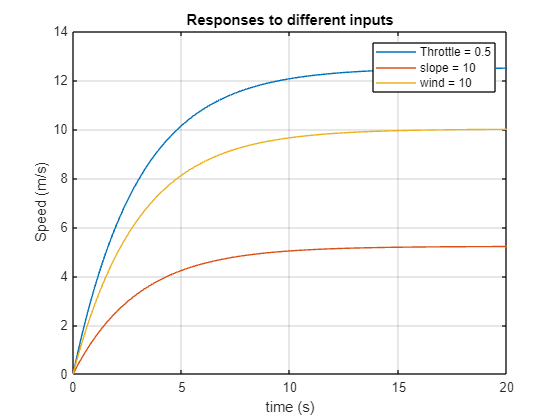

plot(time,yr*throttle,time,ys*sin(slope*pi/180),time,yw*wind)
legend(['Throttle = ',num2str(throttle)],['Slope = ',num2str(slope)],['Wind = ',num2str(wind)])
title('Open-loop speed responses to different inputs')
xlabel('time (s)')
ylabel('Speed (m/s)')
grid

## 5. Interface and user interaction

The image shows a car going up or down a slope.

- Only headwind is included so this is indicated in the figure. 

- The red and green posts are used to represent movement. The red is the car speed and the green moves at the steady-state speed one would achieve with no slope and no wind.

- The animation runs for about 10 seconds to show the responses in the current scenario; this includes animation of the line plots.

The user can change only a few parameters as we want to keep the app simple and transparent to use.

- The mass, friction and engine power parameters which determine the car model

- Selection of road slope and wind speed.

The parameters can only take a finite number of discrete values, as on the sliders, to avoid decimal places.

Users can run the simulation with various choices of parameters and overlay the results so they can build a picture and understanding of the impact of different changes. To refresh and begin again, use the refresh button.

You can turn off the animation to give quicker results using the 'animation/no animation' button.